[trainimages trainlabels] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte',60000 ,0);

[images labels] = readMNIST('train-images.idx3-ubyte', 'train-labels.idx1-ubyte',10000 ,0);

[features] = extractfeatureswithHOG(trainimages(:,:,1), [2 2]);

# K-meams + scaling

[https://abpaudel.com/blog/mnist-sequence-feature-extraction/](https://abpaudel.com/blog/mnist-sequence-feature-extraction/)

extractfeatureswithWaveletScattering(images(:,:,1:4));
im = images(:,:,:)

# Fast-Fourier

load xbox
sf = waveletScattering2('ImageSize',size(xbox))
smat = featureMatrix(sf,xbox);
imshow(smat)

im = images(:,:,1)*255;

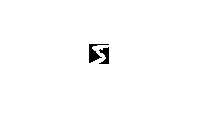

figure
imshow(im)

# HOG Features 

function [features] = extractfeatureswithHOG(images, cellSize)
    hogFeatureSize = length(extractHOGFeatures(images(:,:,1), 'CellSize', cellSize));
    [~, ~, nimages] = size(images);
    features = zeros(nimages, hogFeatureSize);
    for i = 1:nimages
        im = images(:,:,i);
        im = imbinarize(im);
        features(1,:) = extractHOGFeatures(im, 'CellSize', cellSize);
    end
end

[https://es.mathworks.com/help/supportpkg/android/ref/digit-classification-using-hog-features-on-mnist-database.html](https://es.mathworks.com/help/supportpkg/android/ref/digit-classification-using-hog-features-on-mnist-database.html)

# Wavelet Scattering

[https://es.mathworks.com/help/wavelet/examples/digit-classification-with-wavelet-scattering.html](https://es.mathworks.com/help/wavelet/examples/digit-classification-with-wavelet-scattering.html)

function [features] = extractfeatureswithWaveletScattering(images)
    sf = waveletScattering2('ImageSize', size(images(:,:,1)));
    [~, ~, nimages] = size(images);
    for i = 1:nimages
        im = images(:,:,i);
        if (i == 1)
           feature  = helperScatImages(sf,im)
           l = length(feature);
           features = zeros(nimages, l);
           features(1,:) = feature;
        else
            features(i,:)  = helperScatImages(sf,im)
        end
    end
end
function features = helperScatImages(sf,x)
% This function is only to support examples in the Wavelet Toolbox.
% It may change or be removed in a future release.
% Copyright 2018 MathWorks
    smat = featureMatrix(sf,x,'transform','log');
    features = mean(mean(smat,2),3);
end

# Layer